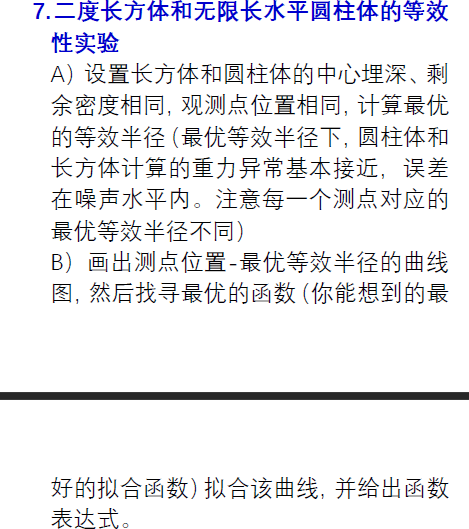

- x, xcenter, X, a, R, H, h, D: 米 (m)

- 含义：沿测线的水平位置、中心位置、平移后的坐标、长方体半宽、圆柱半径、上/下界深度、圆柱中心深度

- sigma (Δρ): 千克/立方米 (kg/m³)

- 含义：密度差（体密度或密度对比）

- lambda: 千克/米 (kg/m)

- 定义：lambda = sigma · π · R²（圆柱每单位长度质量）

- G: 立方米·千克⁻¹·秒⁻² (m³·kg⁻¹·s⁻²)

- 典型值：6.67430×10⁻¹¹ m³·kg⁻¹·s⁻²

- grectangular, gcylinder, deltag: 米/秒² (m/s²)

- 常用展示单位：mGal（1 mGal = 1×10⁻⁵ m/s²）

- pi: 无量纲

xcordina= -2000:1:2000;  
G=6.67e-11;
sigma=10;
xcenter=0;
H=30;
h=10;
a=100;
R=50;
lambda=sigma*pi*R^2;
D=h+(H-h)/2;


grectangular=rectangular(H,a,h,xcordina,xcenter,sigma);
gcylinder=cylinder(D,G,xcordina,lambda);

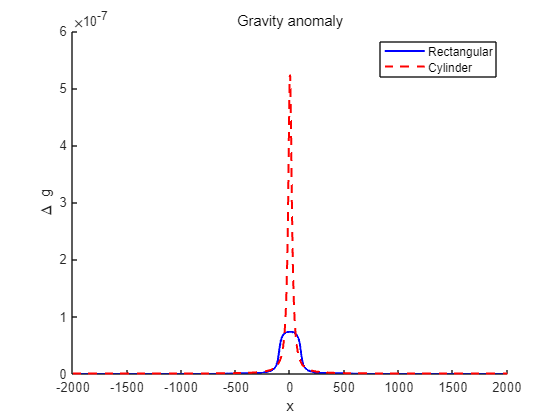

figure; hold on; 
plot(xcordina, grectangular, 'b-', 'LineWidth', 1.5);
plot(xcordina , gcylinder, 'r--', 'LineWidth', 1.5);
xlabel('x');
ylabel('\Delta g');
legend('Rectangular', 'Cylinder');
title('Gravity anomaly');

R_opt=grectangular.*(xcordina.^2+D.^2)./2*G*sigma*pi*D

R_opt = 1.0e-11 *

    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242    0.2242


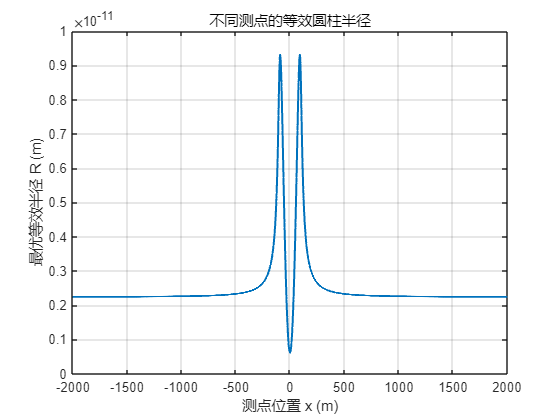

figure; 
plot(xcordina, R_opt, 'LineWidth', 1.5);
xlabel('测点位置 x (m)');
ylabel('最优等效半径 R (m)');
title('不同测点的等效圆柱半径');
grid on;

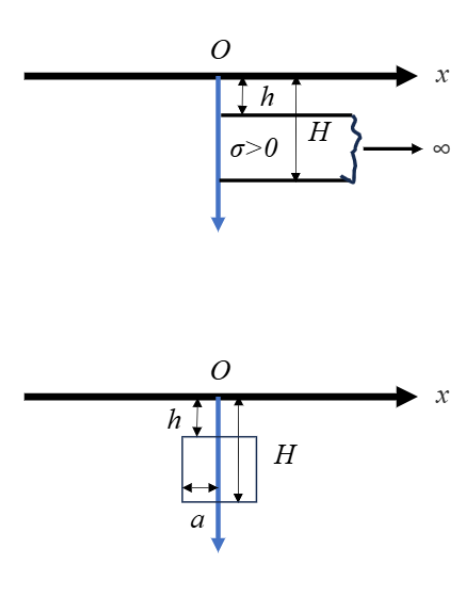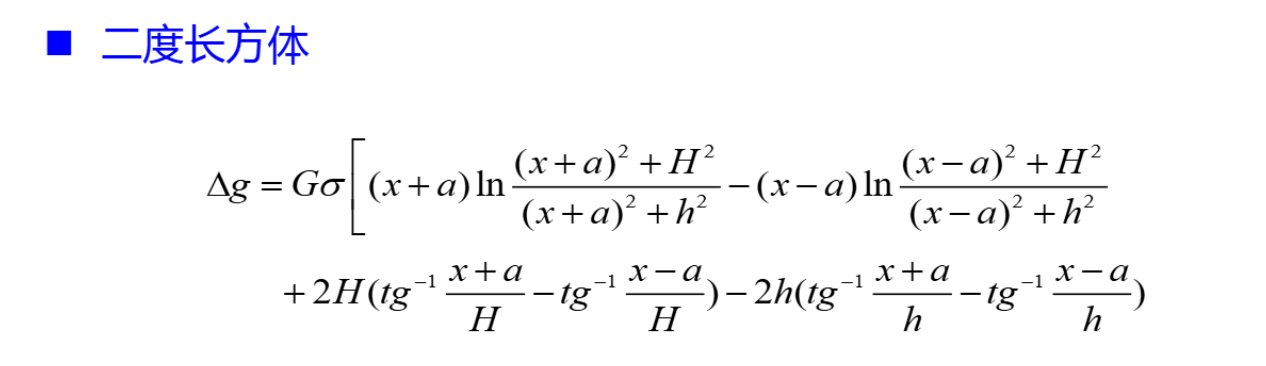

function [deltag] = rectangular(H,a,h,x,xcenter,sigma)
    G = 6.67e-11;  
    X=x-xcenter;
    deltag = G * sigma * ( ...
        (X+a) .* log(((X+a).^2 + H^2) ./ ((X+a).^2 + h^2)) ...
        - (X-a) .* log(((X-a).^2 + H^2) ./ ((X-a).^2 + h^2)) ...
        + 2*H * (atan((X+a)./H) - atan((X-a)./H)) ...
        - 2*h * (atan((X+a)./h) - atan((X-a)./h)) ...
    );
end



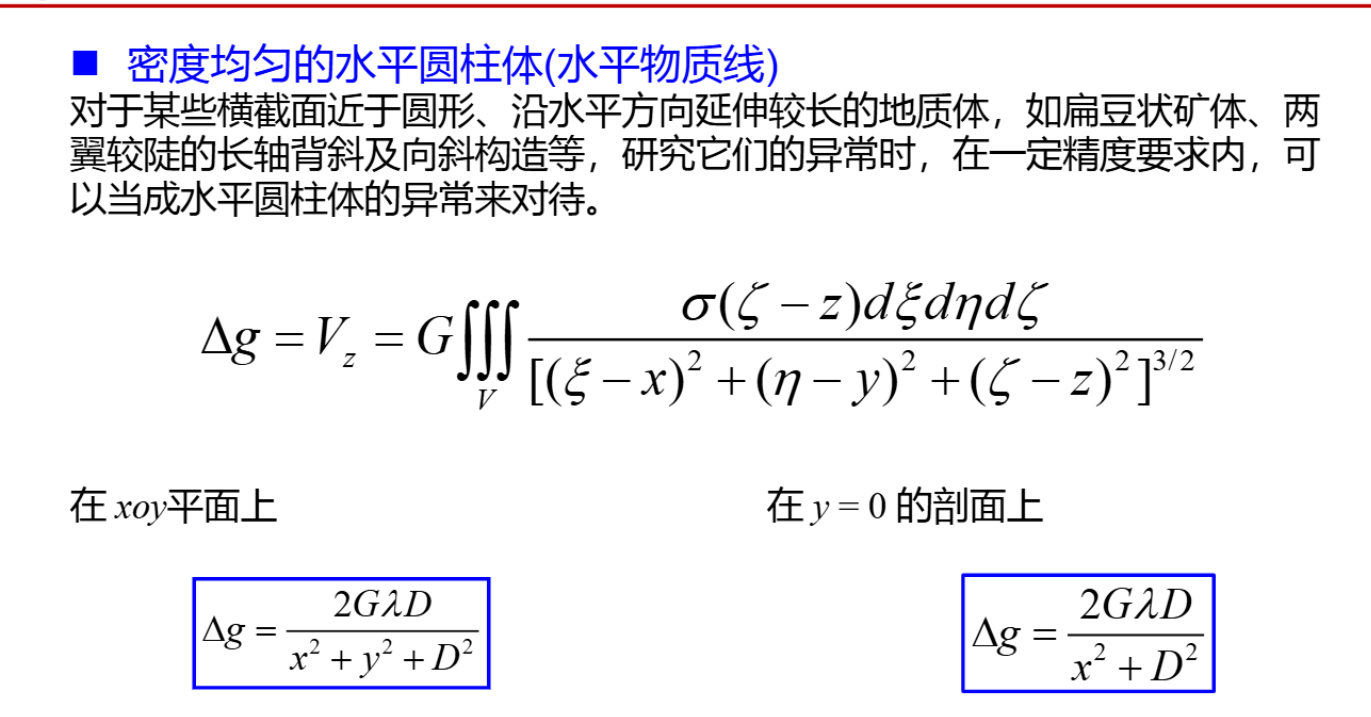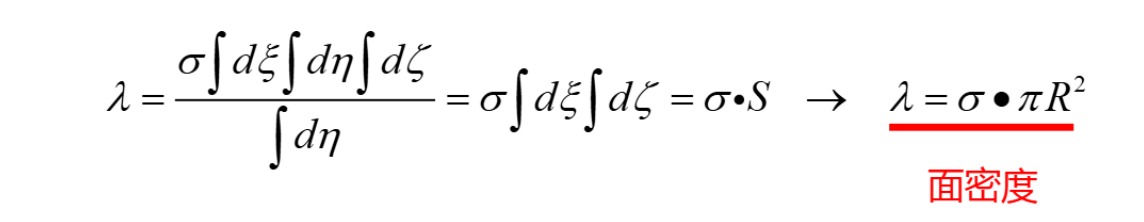


function [deltag] = cylinder(D,G,x,lambda)
     deltag=2*G*lambda*D./(x.^2+D.^2);
 end